## Material Properties

close all;
clear;

% Matboard dimensions (from in to mm)
matboard_w = 32 * 25.4

matboard_w = 812.8000

matboard_h = 40 * 25.4

matboard_h = 1016

matboard_t = 0.05 * 25.4

matboard_t = 1.2700

SA_board = matboard_w * matboard_h

SA_board = 8.2580e+05


% Matboard properties
sigma_tens = 30

sigma_tens = 30

sigma_comp = 6

sigma_comp = 6

shear_strength = 4

shear_strength = 4

youngs_modulus = 4000

youngs_modulus = 4000

poissons_ratio = 0.2

poissons_ratio = 0.2000


% Glue properties
shear_strength_glue = 2

shear_strength_glue = 2

## Moment and Shear Envelopes

L = 1200;  % Length of bridge
n = L+1;  % Number of points
P = 400;  % Total weight of train [N]
n_train = L-960+1;  % Number of train locations

lhs_dist = linspace(0, L, n);

% Offset by 1 because MALDLAB indexes with 1
% Offset by 1 more to shift cumsum one left
x_shear_start_locations = [52, 228, 392, 568, 732, 908] + 2;
x_train_loads = [-P/6, -P/6, -P/6, -P/6, -P/6, -P/6];
start_shear_all = (720-(0:1:n_train-1)')/3;  % Column vector of all possible starting shears
all_train_locations = zeros(n_train, n);

for i = 0:n_train-1
    all_train_locations(i+1, x_shear_start_locations+i) = x_train_loads;
end

% Each row is an SFD for each train location
all_shear = zeros(n_train, n);
all_shear(:,1) = start_shear_all;
all_shear = all_shear + all_train_locations;
all_shear = cumsum(all_shear, 2);

% Each row is a BMD for each train location
all_moment = cumsum(all_shear, 2);
all_moment = all_moment - start_shear_all;

x = 76;  % Location of the train (not needed anymore)

% Shear and moment envelopes
shear_envelope = max(abs(all_shear));
moment_envelope = max(all_moment);

max_shear = max(shear_envelope)

max_shear = 240.0000

max_moment = max(moment_envelope)

max_moment = 6.9445e+04


% If querying x_shear and x_moment is required
% x_shear = all_shear(x+1,:);
% x_moment = all_moment(x+1,:);

## Bridge Geometry

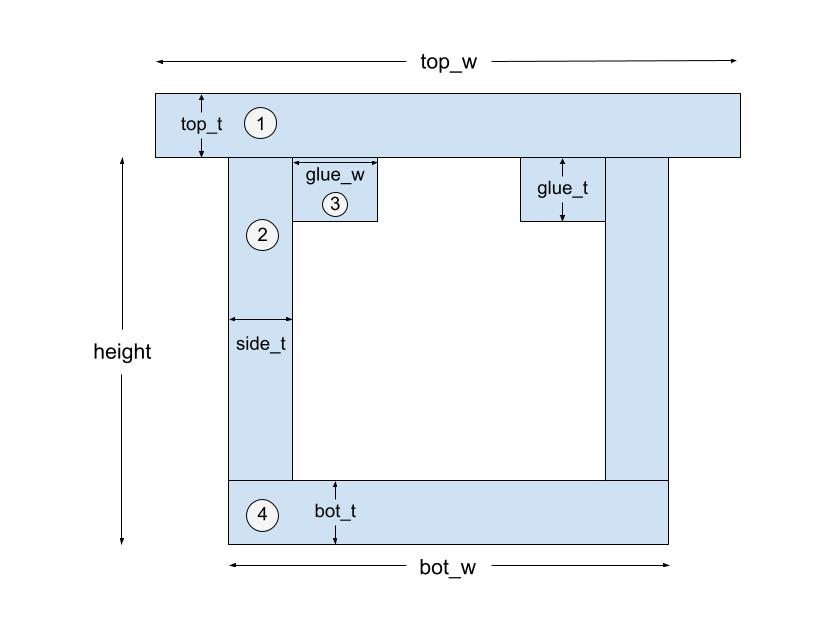

% Design 0 params followed by an underscore
top_w_ = 100;
bot_w_ = 80;
height_ = 75;
top_t_ = 1.27;
bot_t_ = 1.27;
side_t_ = 1.27;
glue_w_ = 5;  % Not including thickness of side
glue_t_ = 1.27;
diaphragm_sep_ = 400;

% New params (add, subtract, multiply old params)
top_w = top_w_ + 20 

top_w = 120

bot_w = bot_w_ - 5

bot_w = 75

height = height_ + 40

height = 115

top_t = top_t_ * 2

top_t = 2.5400

bot_t = bot_t_

bot_t = 1.2700

side_t = side_t_

side_t = 1.2700

glue_w = glue_w_

glue_w = 5

glue_t = glue_t_

glue_t = 1.2700

diaphragm_sep = diaphragm_sep_ / 2

diaphragm_sep = 200

## Cross-Sectional Properties

% Areas of split up sections
area_1 = top_t * top_w

area_1 = 304.8000

area_2 = (height-bot_t) * side_t

area_2 = 144.4371

area_3 = glue_w * glue_t

area_3 = 6.3500

area_4 = bot_t * bot_w

area_4 = 95.2500


% Height of each area's centroidal axis from base
y1 = height + top_t/2

y1 = 116.2700

y2 = (height+bot_t) / 2

y2 = 58.1350

y3 = height - glue_t/2

y3 = 114.3650

y4 = bot_t/2

y4 = 0.6350


% Local moment of inertias of each area
I1 = top_w*(top_t^3) / 12

I1 = 163.8706

I2 = side_t*((height-bot_t)^3) / 12

I2 = 1.5569e+05

I3 = glue_w*(glue_t^3) / 12

I3 = 0.8535

I4 = bot_w*(bot_t^3) / 12

I4 = 12.8024


% Total area
tot_area = area_1 + 2*area_2 + 2*area_3 + area_4

tot_area = 701.6242


% Centroidal axis
y_bar = (area_1*y1 + 2*area_2*y2 + 2*area_3*y3 + area_4*y4) / tot_area

y_bar = 76.6019


% Distance from global centroidal axis to local centoridal axes of areas
d1 = y1 - y_bar

d1 = 39.6681

d2 = y2 - y_bar

d2 = -18.4669

d3 = y3 - y_bar

d3 = 37.7631

d4 = y_bar - y4  % Order doesn't really matter but just for illustrative purposes

d4 = 75.9669


% Parallel axis theorem
sec1 = area_1*(d1^2) + I1

sec1 = 4.7979e+05

sec2 = 2 * (area_2*(d2^2) + I2)

sec2 = 4.0988e+05

sec3 = 2 * (area_3*(d3^2) + I3)

sec3 = 1.8113e+04

sec4 = area_4*(d4^2) + I4

sec4 = 5.4970e+05


% Moment of inertia
I = sec1 + sec2 + sec3 + sec4

I = 1.4575e+06


% Q values
Q_cent = (bot_w-2*side_t)*bot_t*(y_bar-bot_t/2) + 2*y_bar*side_t*(y_bar/2)

Q_cent = 1.4443e+04

Q_glue = area_1 * (height-y_bar + top_t/2)

Q_glue = 1.2091e+04

## Non-Thin Plate Stresses

% Maximum abs(shear value) and abs(moment value)
[shear_max, shear_max_index] = max(shear_envelope);
[moment_max, moment_max_index] = max(moment_envelope);

% Largest tensile and compressive stress at every x
sigma_top_comp = moment_envelope*(height+top_t-y_bar) / I

sigma_top_comp =          0    0.0067    0.0135    0.0202    0.0270    0.0337    0.0404    0.0472    0.0539    0.0607    0.0674    0.0742    0.0809    0.0876    0.0944    0.1011    0.1079    0.1146    0.1213    0.1281    0.1348    0.1416    0.1483    0.1550    0.1618    0.1685    0.1753    0.1820    0.1888    0.1955    0.2022    0.2090    0.2157    0.2225    0.2292    0.2359    0.2427    0.2494    0.2562    0.2629    0.2696    0.2764    0.2831    0.2899    0.2966    0.3034    0.3101    0.3168    0.3236    0.3303


sigma_bot_tens = moment_envelope*y_bar / I

sigma_bot_tens =          0    0.0126    0.0252    0.0378    0.0505    0.0631    0.0757    0.0883    0.1009    0.1135    0.1261    0.1388    0.1514    0.1640    0.1766    0.1892    0.2018    0.2144    0.2270    0.2397    0.2523    0.2649    0.2775    0.2901    0.3027    0.3153    0.3280    0.3406    0.3532    0.3658    0.3784    0.3910    0.4036    0.4163    0.4289    0.4415    0.4541    0.4667    0.4793    0.4919    0.5046    0.5172    0.5298    0.5424    0.5550    0.5676    0.5802    0.5929    0.6055    0.6181



% Largest shear stress at the centroidal axis at every x
T_cent = (shear_envelope*Q_cent) / (I*(2*side_t))

T_cent =     0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363    0.9363



% Largest shear stress at glue joints at every x
T_glue = (shear_envelope*Q_glue) / (I*(2*glue_w))

T_glue =     0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991    0.1991



% Max values for sigma_top_comp, sigma_bot_tens, T_cent, T_glue
sigma_top_comp_max = max(sigma_top_comp)

sigma_top_comp_max = 1.9506

sigma_bot_tens_max = max(sigma_bot_tens)

sigma_bot_tens_max = 3.6499

T_cent_max = max(T_cent)

T_cent_max = 0.9363

T_glue_max = max(T_glue)

T_glue_max = 0.1991

## Thin Plate Buckling

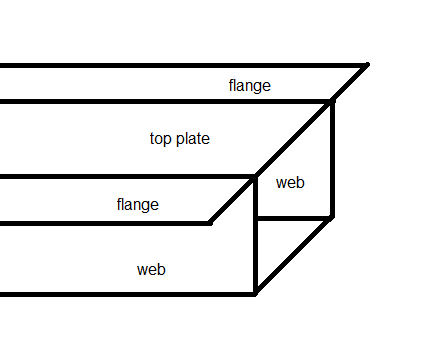

% Case 1: Bucking of the top plate due to flexural compression
t_top_plate = top_t

t_top_plate = 2.5400

b_in = bot_w - side_t

b_in = 73.7300

stress_top_plate = (4*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_top_plate/b_in)^2

stress_top_plate = 16.2685


% Case 2: Buckling of the flanges due to flexural compression
t_flange = top_t

t_flange = 2.5400

b_out = (top_w-bot_w)/2 + side_t/2

b_out = 23.1350

stress_side_flange = (0.425*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_flange/b_out)^2

stress_side_flange = 17.5560


% Case 3: Buckling of the webs due to varying flexural compression
t_web_flex = side_t

t_web_flex = 1.2700

y_top = height - glue_t/2 - y_bar

y_top = 37.7631

stress_varying_shear = (6*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * (t_web_flex/y_top)^2

stress_varying_shear = 23.2557


% Case 4: Shear buckling
t_web_shear = side_t

t_web_shear = 1.2700

h_web = height - glue_t/2 - bot_t/2

h_web = 113.7300

stress_shear_buckle = (5*pi^2*youngs_modulus)/(12*(1-poissons_ratio^2)) * ((t_web_shear/h_web)^2 + (t_web_shear/diaphragm_sep)^2)

stress_shear_buckle = 2.8276

## Factor of Safety

% Flexural related
FOS_tension = sigma_tens ./ sigma_bot_tens

FOS_tension = 1.0e+14 *

       Inf    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


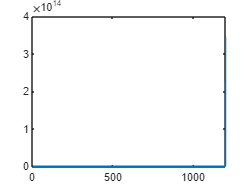

plot(lhs_dist, FOS_tension)

FOS_comp = sigma_comp ./ sigma_top_comp

FOS_comp = 1.0e+14 *

       Inf    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


FOS_flexbuck1 = stress_top_plate ./ sigma_top_comp

FOS_flexbuck1 = 1.0e+14 *

       Inf    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


FOS_flexbuck2 = stress_side_flange ./ sigma_top_comp

FOS_flexbuck2 = 1.0e+14 *

       Inf    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


FOS_flexbuck3 = stress_varying_shear ./ sigma_top_comp

FOS_flexbuck3 = 1.0e+14 *

       Inf    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Shear related FOS
FOS_shear = shear_strength ./ T_cent

FOS_shear =     4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720    4.2720


FOS_shear_glue = shear_strength_glue ./ T_glue

FOS_shear_glue =    10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453   10.0453


FOS_shear_buck = stress_shear_buckle ./ T_cent

FOS_shear_buck =     3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198    3.0198


## Shear Force Capacities + Bending Moment Capacities

% Flexural related capacities
M_fail_tens = FOS_tension .* moment_envelope

M_fail_tens = 1.0e+05 *

       NaN    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080    5.7080


M_fail_comp = FOS_comp .* moment_envelope

M_fail_comp = 1.0e+05 *

       NaN    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361    2.1361


M_fail_buck1 = FOS_flexbuck1 .* moment_envelope

M_fail_buck1 = 1.0e+05 *

       NaN    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919    5.7919


M_fail_buck2 = FOS_flexbuck2 .* moment_envelope

M_fail_buck2 = 1.0e+05 *

       NaN    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503    6.2503


M_fail_buck3 = FOS_flexbuck3 .* moment_envelope

M_fail_buck3 = 1.0e+05 *

       NaN    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795    8.2795



% Shear related capacities
V_fail_shear = FOS_shear .* shear_envelope

V_fail_shear = 1.0e+03 *

    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253    1.0253


V_fail_shear_glue = FOS_shear_glue .* shear_envelope

V_fail_shear_glue = 1.0e+03 *

    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109    2.4109


V_fail_shear_buck = FOS_shear_buck .* shear_envelope

V_fail_shear_buck =   724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590  724.7590


## Summary of Minimum FOSs

tension_FOS = min(FOS_tension)

tension_FOS = 8.2194

comp_FOS = min(FOS_comp)

comp_FOS = 3.0760

top_buck_FOS = min(FOS_flexbuck1)

top_buck_FOS = 8.3402

flange_buck_FOS = min(FOS_flexbuck2)

flange_buck_FOS = 9.0003

web_buck_FOS = min(FOS_flexbuck3)

web_buck_FOS = 11.9223

shear_FOS = min(FOS_shear)

shear_FOS = 4.2720

glue_FOS = min(FOS_shear_glue)

glue_FOS = 10.0453

shear_buck_FOS = min(FOS_shear_buck)

shear_buck_FOS = 3.0198

## Surface Area

% Surface areas for each matboard area with stacking considered
SA1 = top_w * L * (top_t/top_t_);
SA2 = (height-bot_t) * L * (side_t/side_t_);
SA3 = glue_w * L * (glue_t/glue_t_);
SA4 = bot_w * L * (bot_t/bot_t_);

% Surface areas for each diaphragm
SAd = (bot_w-2*side_t) * (height-bot_t);  % Upper bound
extra = 0;  % Manually edit - extra diaphragms
num_diaphragms = (L/diaphragm_sep) + extra;

% Total surface area
SA = SA1 + 2*SA2 + 2*SA3 + SA4 + SAd*num_diaphragms

SA = 7.1240e+05


% If possible, try to be lower than 0.8
Surface_area_percent = SA/SA_board

Surface_area_percent = 0.8627

## Graphs

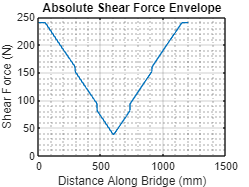

% Graphing Shear envelope
figure
plot(lhs_dist, shear_envelope)
grid on
grid minor
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Absolute Shear Force Envelope")

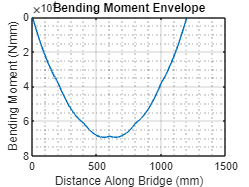


% Graphing moment envelope
figure
plot(lhs_dist, moment_envelope)
grid on
grid minor
set(gca, 'YDir', 'reverse')  % Flip y-axis
yline(0)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
title("Bending Moment Envelope")

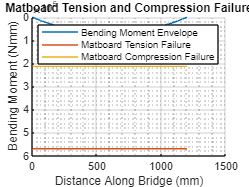


% Matboard tension and compression failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_tens)
plot(lhs_dist, M_fail_comp)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Tension and Compression Failure")
legend("Bending Moment Envelope", "Matboard Tension Failure", "Matboard Compression Failure")
hold off;

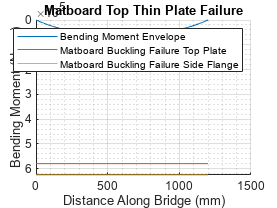


% Matboard top thin plate failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck1)
plot(lhs_dist, M_fail_buck2)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Top Thin Plate Failure")
legend("Bending Moment Envelope", "Matboard Buckling Failure Top Plate", "Matboard Buckling Failure Side Flange")
hold off;

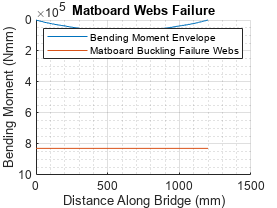


% Matboard webs failure
figure
hold on;
set(gca, 'YDir', 'reverse') 
plot(lhs_dist, moment_envelope)
plot(lhs_dist, M_fail_buck3)
xlabel("Distance Along Bridge (mm)")
ylabel("Bending Moment (Nmm)")
grid on
grid minor
title("Matboard Webs Failure")
legend("Bending Moment Envelope", "Matboard Buckling Failure Webs")
hold off;

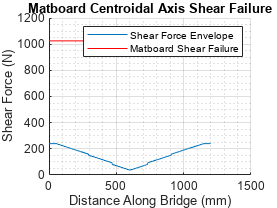


% Matboard centroidal axis shear failure
figure
hold on
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear, "r")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
grid on
grid minor
title("Matboard Centroidal Axis Shear Failure")
legend("Shear Force Envelope", "Matboard Shear Failure")
hold off

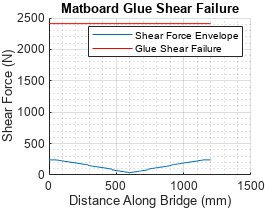


% Matboard glue shear failure
figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear_glue, "r")
legend("Shear Force Envelope", "Glue Shear Failure")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Matboard Glue Shear Failure")
grid on
grid minor
hold off

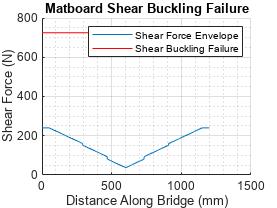


% Matboard shear buckling failure
figure 
hold on 
plot(lhs_dist, shear_envelope)
plot(lhs_dist, V_fail_shear_buck, "r")
legend("Shear Force Envelope", "Shear Buckling Failure")
xlabel("Distance Along Bridge (mm)")
ylabel("Shear Force (N)")
title("Matboard Shear Buckling Failure")
grid on
grid minor
hold off